# Determine ADRC Parameters

ADRC requires the approximation of the system dynamics. Most commonly the First- and Second-order approximation is used:

- First-order approximation — $\dot{\;y\;} \left(t\right)\;=b_0 u\left(t\right)+f\left(t\right)$

- Second-order approximation — $\ddot{\;y\;} \left(t\right)\;=b_0 u\left(t\right)+f\left(t\right)$

The open-loop analysis of the IM model via a step response shows first-order dynamics of input (yellow) and output toruq (blue):

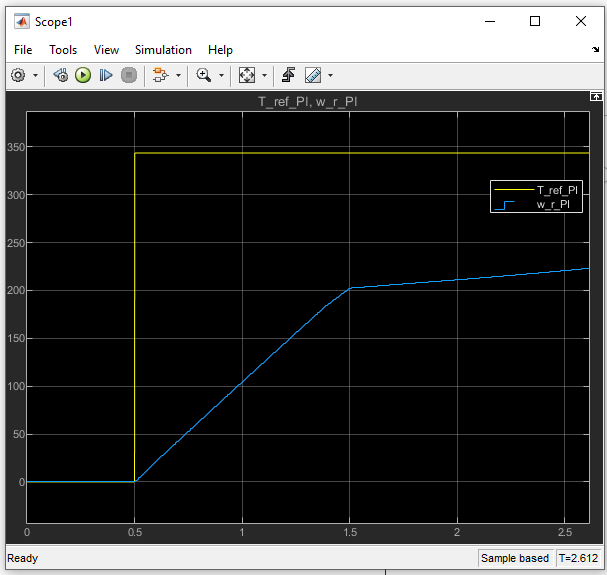

Thus first-order approximation is used.

## First-order Approximation of IM

The parameter a is calculated via following equation:


$$a=\frac{y\left(\textrm{end}\right)-y\left(0\right)}{t\left(\textrm{end}\right)-t\left(0\right)}$$


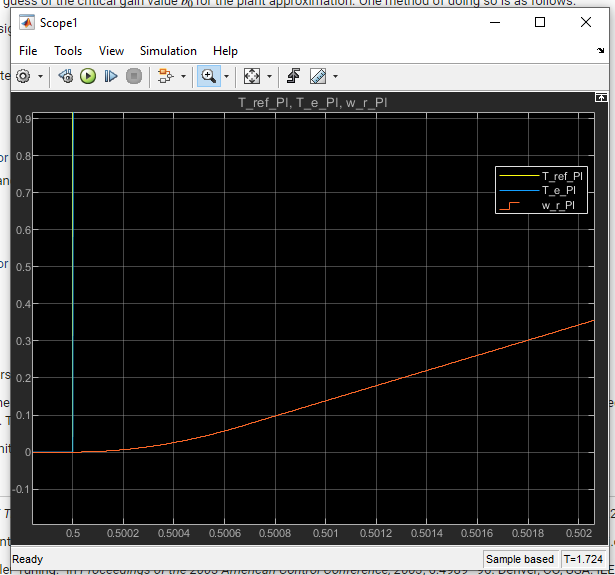

a = (104.4 - 0)/(1 - 0.5);

## Second-order Approximation of IM

The parameter a is calculated via following equation:


$$a=\frac{2\left(y\left(\textrm{end}\right)-y\left(0\right)\right)}{\left(t\left(\textrm{end}\right)-t\left(0\right)\right)2}$$


a = 2*(0.3 - 0)/(0.5018 - 0.5)^2;

To calculate parameter b following equation is used:


$$b_0 =\frac{a}{u_{\textrm{OL}} }$$


b = a/(1.5*T_nom);

The controller bandwith $\omega_C$ and the observer bandwith $\omega_O$ can arbitrarely set and tuned to desired control-system performance. The observer needs to converge faster than the controller. In general, the observer bandwidth is set to 5 to 10 times of controller bandwith:

omega_C = 250; % rad/sec
omega_O = omega_C * 7;

*Source: *[*https://de.mathworks.com/help/slcontrol/ug/active-disturbance-rejection-control.html*](https://de.mathworks.com/help/slcontrol/ug/active-disturbance-rejection-control.html) 